# 形态学图像处理

## 9.2 膨胀和腐蚀

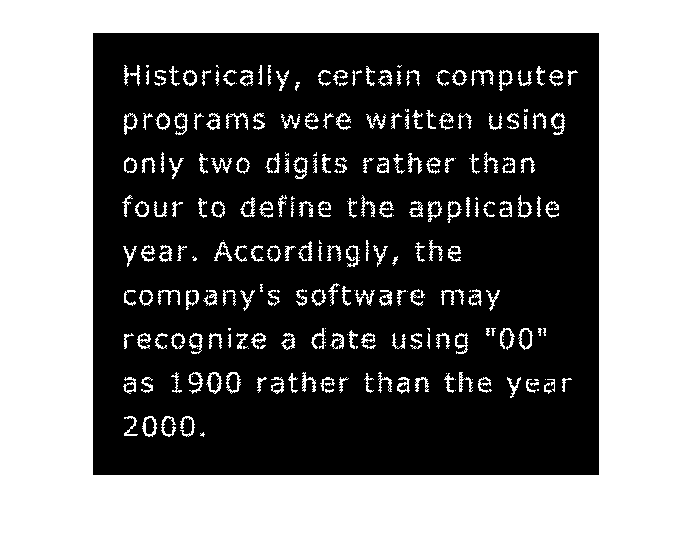

% 9.2.2 膨胀
% 例 9.1 膨胀应用

A = imread('./DIP-Ex/pic/dipum_images_ch09/Fig0906(a)(broken-text).tif');
figure;
imshow(A, []);

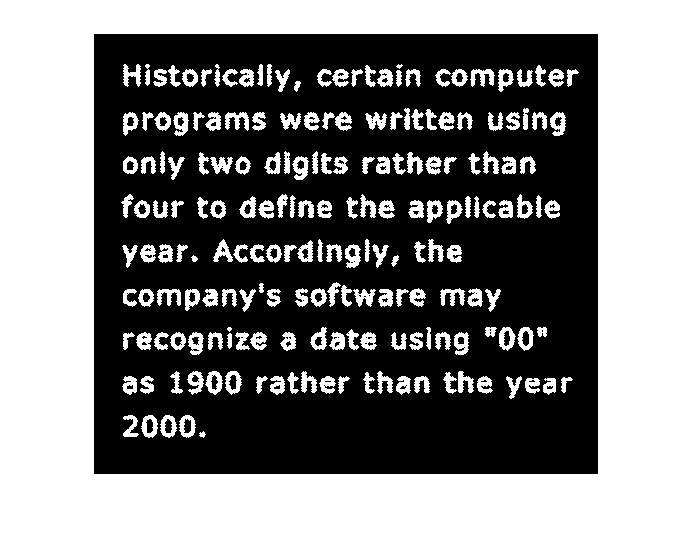

B = [0 1 0; 1 1 1; 0 1 0];
A2 = imdilate(A, B); % 用 B 膨胀 A
figure;
imshow(A2, []); % 膨胀后 e a 被桥接

% 9.2.2 结构元素分解
% 结构元素如果能被分解为两个子结构的膨胀结果，[这里要写到笔记中]

% 9.2.3 strel 创建 SE

% 例 9.2 strel 分解结构元素
se = strel('diamond', 5);
se.Neighborhood

ans = 11×11 logical 数组
   0   0   0   0   0   1   0   0   0   0   0
   0   0   0   0   1   1   1   0   0   0   0
   0   0   0   1   1   1   1   1   0   0   0
   0   0   1   1   1   1   1   1   1   0   0
   0   1   1   1   1   1   1   1   1   1   0
   1   1   1   1   1   1   1   1   1   1   1
   0   1   1   1   1   1   1   1   1   1   0
   0   0   1   1   1   1   1   1   1   0   0
   0   0   0   1   1   1   1   1   0   0   0
   0   0   0   0   1   1   1   0   0   0   0


decomp = getsequence(se); % 提取并检查分解中的单个结构元素
whos % 输出之前变量的信息

  Name          Size              Bytes  Class      Attributes

  A           444x509            225996  logical              
  A2          444x509            225996  logical              
  B             3x3                  72  double               
  SE            1x1                1618  strel                
  ans          11x11                121  logical              
  decomp        4x1                 576  strel                
  f           444x509            225996  logical              
  se            1x1                2264  strel                



% decomp size 为 4 * 1，说明分解为 4 个结构了
decomp(1).Neighborhood

ans = 3×3 logical 数组
   0   1   0
   1   1   1
   0   1   0


decomp(2).Neighborhood

ans = 3×3 logical 数组
   0   1   0
   1   0   1
   0   1   0


decomp(3).Neighborhood

ans = 5×5 logical 数组
   0   0   1   0   0
   0   0   0   0   0
   1   0   0   0   1
   0   0   0   0   0
   0   0   1   0   0


decomp(4).Neighborhood

ans = 3×3 logical 数组
   0   1   0
   1   0   1
   0   1   0


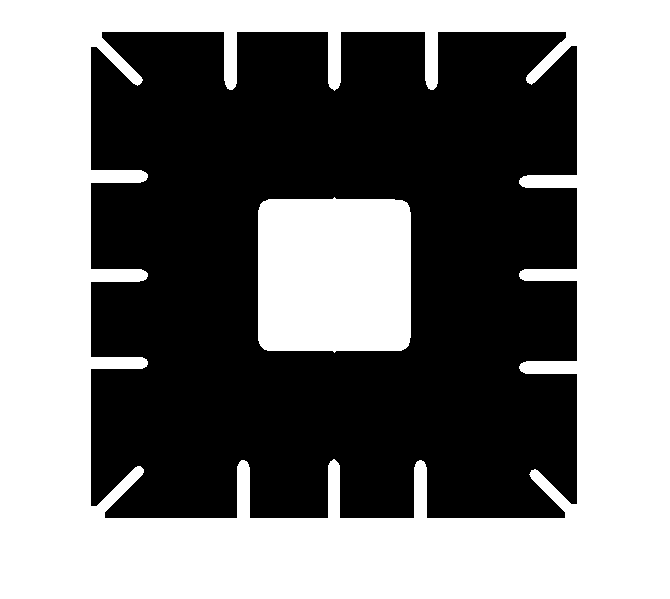

% 9.2.4 腐蚀

% 例 9.3 腐蚀的说明
A = imread('./DIP-Ex/pic/dipum_images_ch09/Fig0908(a)(wirebond-mask).tif');
SE = strel('disk', 10);
A2 = imerode(A, SE);
figure;
imshow(A2, []); % 这里用 半径为 10 圆盘腐蚀

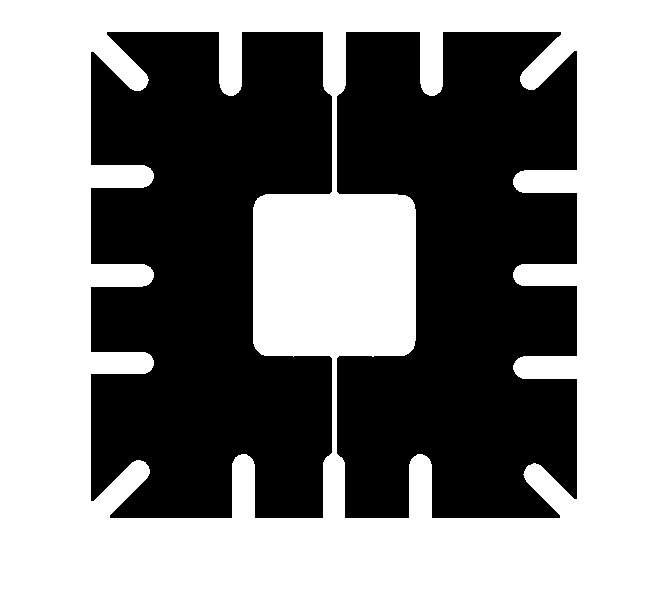

SE = strel('disk', 5);
A2 = imerode(A, SE);
figure;
imshow(A2, []); % 这里用 半径为 5 圆盘腐蚀，粗的线没被腐蚀掉

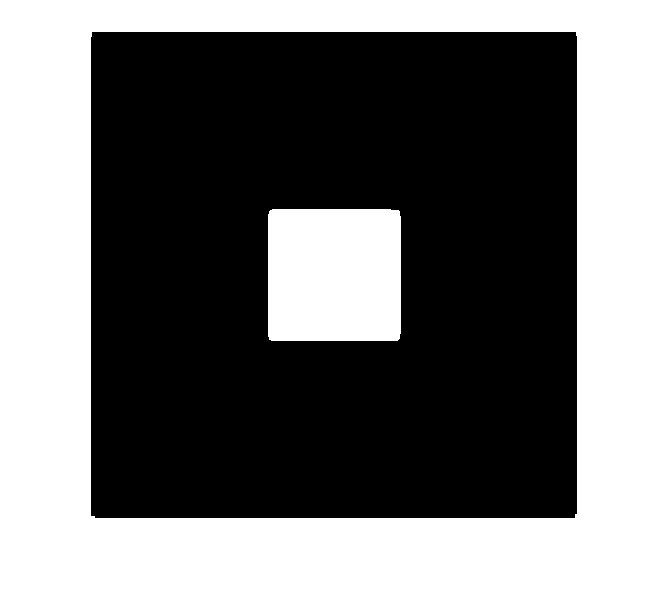

SE = strel('disk', 20);
A2 = imerode(A, SE);
figure;
imshow(A2, []); % 这里用 半径为 20 圆盘腐蚀 只有中心方块保留

## 9.3 膨胀与腐蚀结合

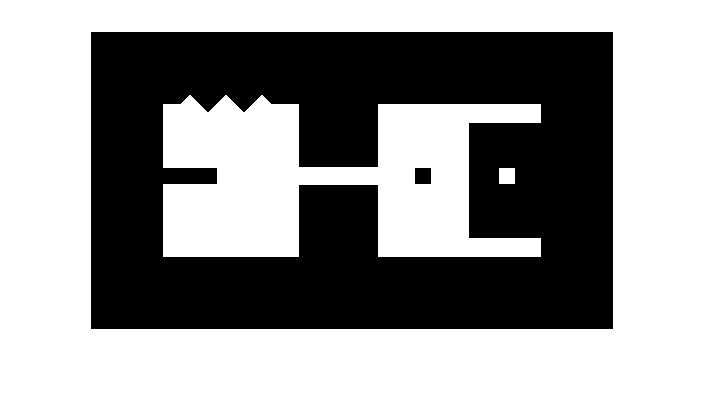

% 9.3.1 开运算闭运算
% 例 9.4 imopen imclose
f = imread('./DIP-Ex/pic/dipum_images_ch09/Fig0910(a)(shapes).tif');
figure;
imshow(f, []);

se = strel('square', 20);
se.Neighborhood

ans = 20×20 logical 数组
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


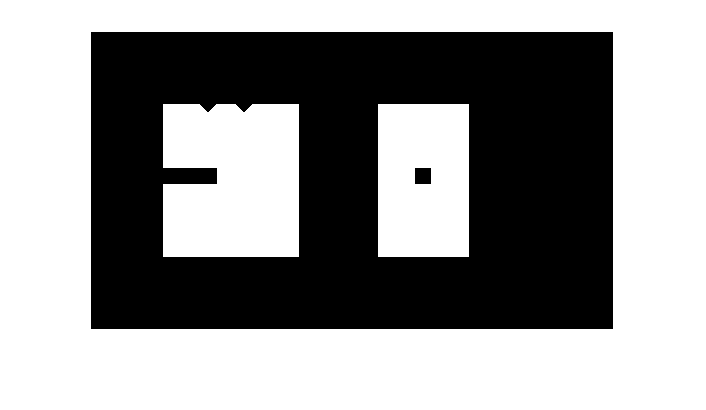

fo = imopen(f, se); % 开运算
figure;
imshow(fo); % 回想一下几何解释，在图像内部平移，可以消除凸起，连接处也被断开

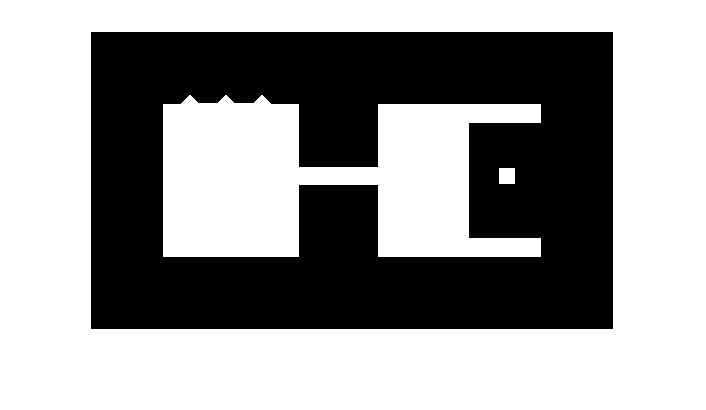

fc = imclose(f, se);
figure;
imshow(fc, []); % 回想一下几何解释，在图像外围平移，是不是会添补向内的空隙，保留向外凸起

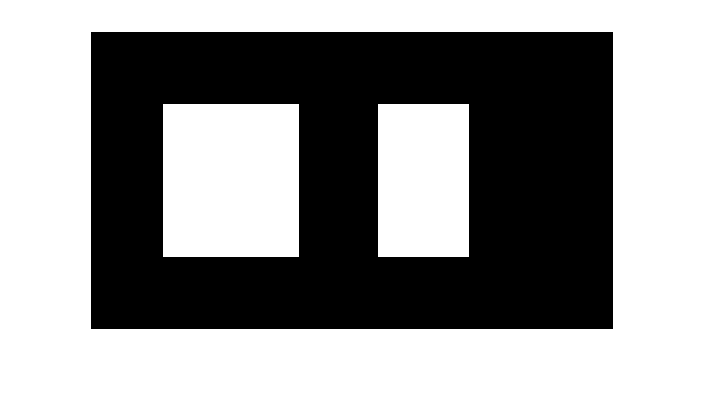

foc = imclose(fo, se); % 开运算后再闭运算，可以平滑目标图像
figure;
imshow(foc, []);

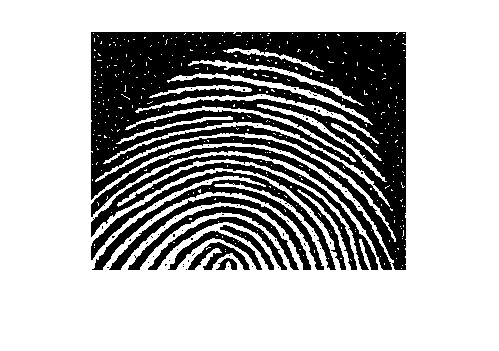

f = imread('./DIP-Ex/pic/dipum_images_ch09/Fig0911(a)(noisy-fingerprint).tif');
figure;
imshow(f, []); % 这是含噪的指纹图

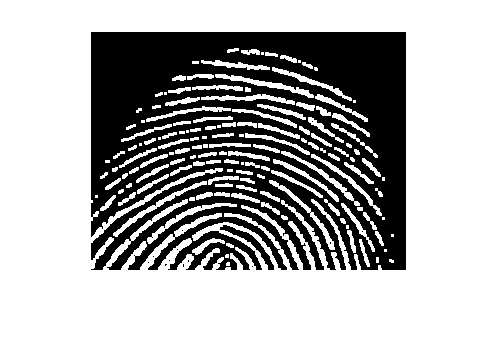

se = strel('square', 3);
fo = imopen(f, se);
figure;
imshow(fo, []);% 利用开运算去除一些毛刺噪声，但是造成了一些内部的断裂(想一想几何解释，结构元再图像内部滚

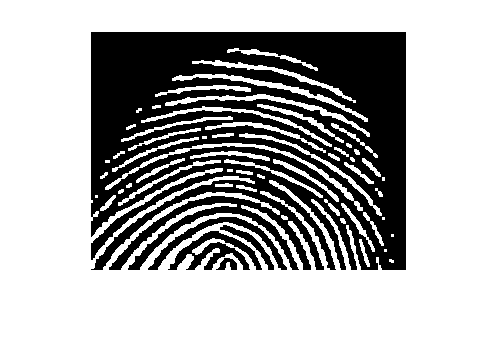

foc = imclose(fo, se); % 再用闭运算填充缺口
figure;
imshow(foc, []);

% 9.3.2 击中 - 不击中变换
% 例 9.5 bwhitmiss
% 此处定义式在第三版，第四版有更新一种更好理解的。如果关于此实验例子不了解，翻看图 9.12
B1 = strel([0 0 0; 0 1 1; 0 1 0]);
B2 = strel([1 1 1; 1 0 0; 1 0 0]);
B1.Neighborhood % 要右边，下边领域像素，注意 B1 对应的 1 的位置

ans = 3×3 logical 数组
   0   0   0
   0   1   1
   0   1   0


B2.Neighborhood % 不要左上|右上|左下|上，注意 B2 对应的 1 位置

ans = 3×3 logical 数组
   1   1   1
   1   0   0
   1   0   0


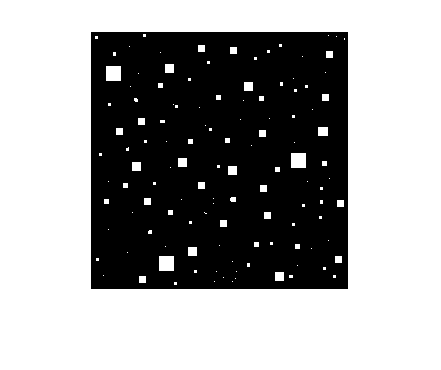

% B1 关心击中，B2 关心不击中，B1 B2 右下角都为 0，说明这是不关心点。
f = imread('./DIP-Ex/pic/dipum_images_ch09/Fig0913(a)(small-squares).tif');
figure;
imshow(f, []);

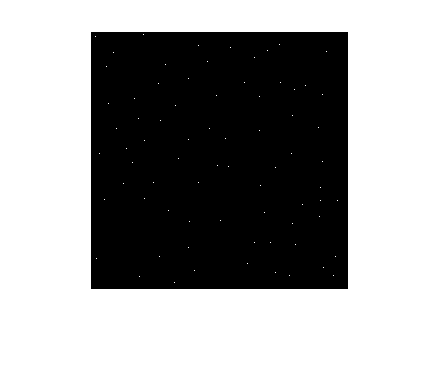

g = bwhitmiss(f, B1, B2);
figure;
imshow(g, []); % 可以对比一下击中 和 不击中分别在哪里，从而达到缩小目标图像的效果

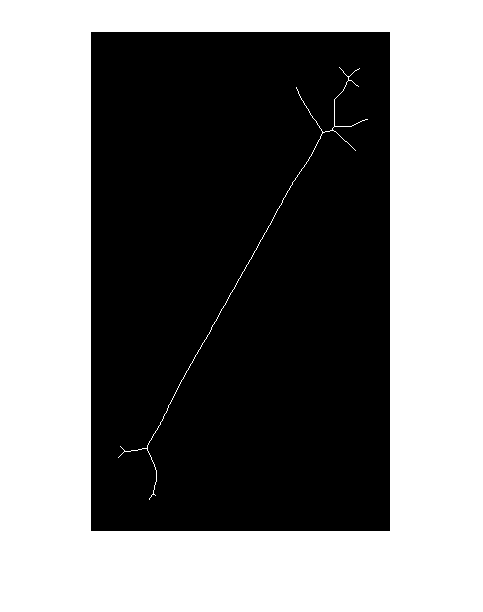

% 9.3.3 使用查找表
% 注意他前头说的例子，如何给一个形状分配一个唯一索引。

% 接下来查找端点
f = imread('./DIP-Ex/pic/dipum_images_ch09/Fig0914(a)(bone-skel).tif');
figure, imshow(f, []);

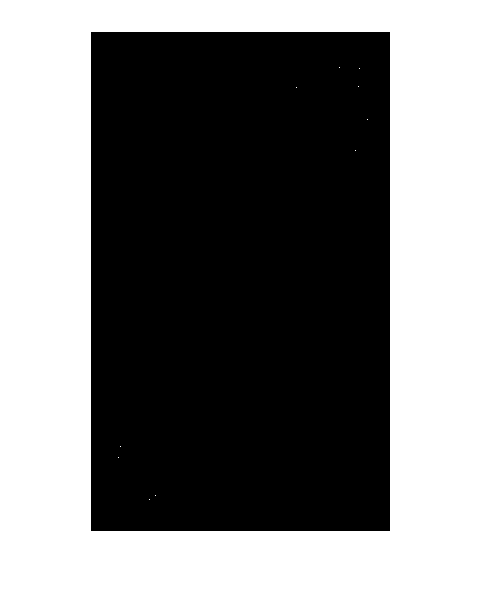

f_e = endpoints(f);
figure, imshow(f_e, []);

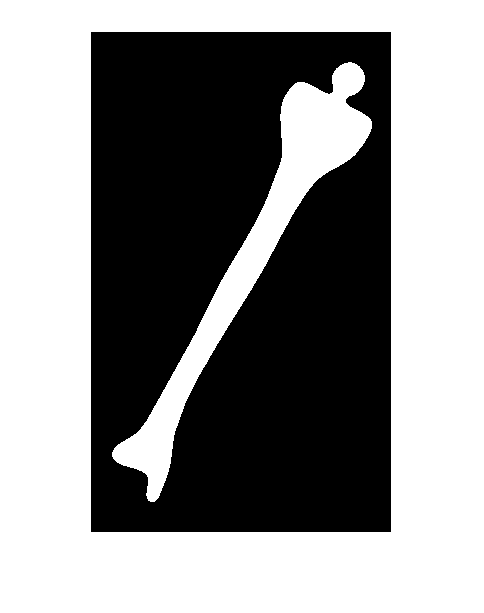

% 9.3.4 bwmorph 基于膨胀腐蚀查找表组合实现操作
f = imread('./DIP-Ex/pic/dipum_images_ch09/Fig0916(a)(bone).tif');
figure;
imshow(f, []);

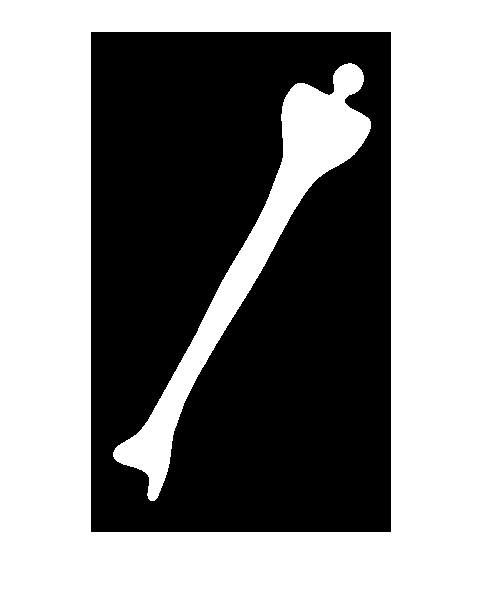

g1 = bwmorph(f, 'thin', 1); % 细化操作 1 次
g2 = bwmorph(f, 'thin', 2); 
g_inf = bwmorph(f, 'thin', inf); % 无数次，直至不能再细化 
figure, imshow(g1, []);

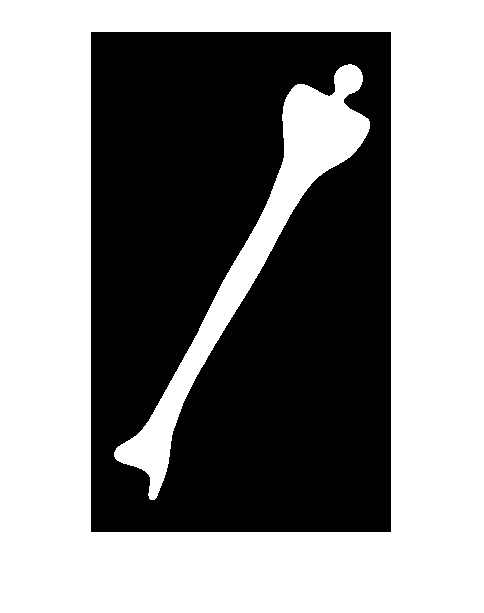

figure, imshow(g2, []);

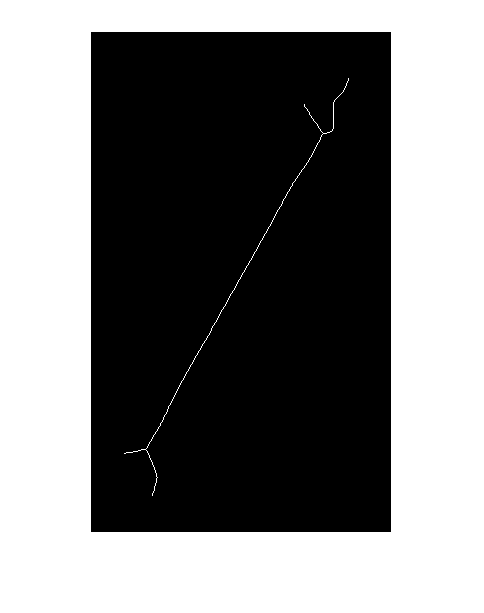

figure, imshow(g_inf, []); % inf 细化会造成一些损失，不能喝骨骼化等同

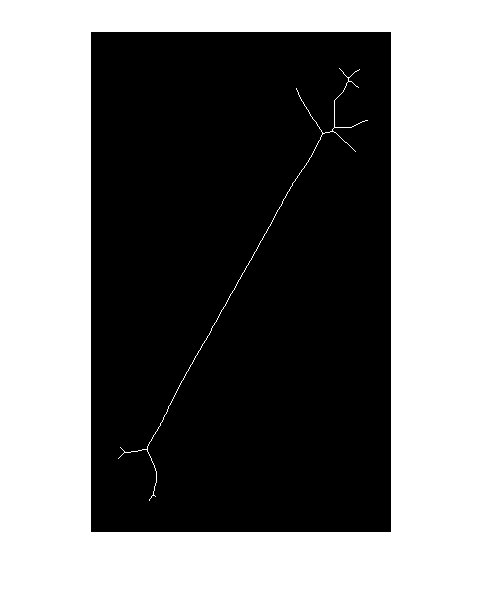

fs = bwmorph(f, 'skel', inf); % 直接进行骨骼化
figure, imshow(fs, []);

## 9.4 标注连接分量

## 函数自定义区

function g = endpoints(f)
    persistent lut % 定义持久变量
    if isempty(lut)
        lut = makelut(@endpoint_fcn, 3); % 传入一个判别函数，得到一个查找表，原理查看实验书 9.3.3。
    end
    g = applylut(f, lut);
end

% 查看此像素是否为端点
function is_end_point = endpoint_fcn(nhood)
    % nhood 是 3 * 3 的二值矩阵表示领域，如果中心元素是端点，就返回 1
    
%     [0 0 0
%      0 1 0
%      0 0 1]
%      [1 0 0
%      0 1 0
%      0 0 0]
%   类似如上的都算端点
    is_end_point = nhood(2, 2) & (sum(nhood(:)) == 2);
end